# Impact of white noise on the different metrics considered here.

We are quite confident that the presence of noise, which is non-dispersive, can qualitatively impact the different metrics. Here we make some figures to show this. 

We show this as a qualitative argument using only a single data set from the model. 

clear all
close all 

% load some model data 
d = 10; 

distance = [10,15]*1e3;

i = 1; 
[mod_traj(i).X, mod_traj(i).Y, mod_traj(i).U, mod_traj(i).V, mod_traj(i).T, depth(i)] = loadpairs(d(i));

depth = -1.4749e+03

    
% get the velocity from forward differencing (will be important for structure functions)
Unew = nan*mod_traj(i).X;
Vnew = nan*mod_traj(i).X;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(mod_traj(i).X)*cor.*cosd(mod_traj(i).Y(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(mod_traj(i).Y)*cor/dt; 

mod_traj(i).U = Unew; 
mod_traj(i).V = Vnew; 

mod_traj(i).U(mod_traj(i).U==-999) = NaN;
mod_traj(i).V(mod_traj(i).V==-999) = NaN;
mod_traj(i).Y(mod_traj(i).X>360-70) = NaN;
mod_traj(i).U(mod_traj(i).X>360-70) = NaN;
mod_traj(i).V(mod_traj(i).X>360-70) = NaN;
mod_traj(i).X(mod_traj(i).X>360-70) = NaN;

 
% add some noise to some model output
Lk = [0.5, 1, 2];

for i =1:length(Lk) 

xrand = Lk(i)*randn(736, 1200);
yrand = Lk(i)*randn(736, 1200);

[Ylrand, Xlrand] = xy2latlon(xrand, yrand, -55, 270); 
Xlrand = Xlrand+360; 


mod_traj_noise(i).X = mod_traj.X + Xlrand - Xlrand(1,:);
mod_traj_noise(i).Y = mod_traj.Y + Ylrand - Ylrand(1,:);

mod_traj_noise(i).T = mod_traj.T;

end

% spectra with noise 
len = 120; 
psi = sleptap(len); 

SLEPTAP calculating tapers of length 120.



CV_noise = zeros(len, 1200);
CV_mod_noise1 = zeros(len, 1200);
CV_mod_noise2 = zeros(len, 1200);
CV_mod_noise3 = zeros(len, 1200);
CV_mod = zeros(len, 1200);

for nseg=1:1200
    CV_mod(:,nseg) = latlon2uv(mod_traj.T(2:121), mod_traj.Y(2:121,nseg), ...
                        mod_traj.X(2:121,nseg), 'forward' )/100;
    CV_noise(:,nseg) = latlon2uv(mod_traj_noise(1).T(2:121), Ylrand(2:121,nseg), ...
                        Xlrand(2:121,nseg), 'forward' )/100;
    CV_mod_noise1(:,nseg) = latlon2uv(mod_traj_noise(1).T(2:121), mod_traj_noise(1).Y(2:121,nseg), ...
                        mod_traj_noise(1).X(2:121,nseg), 'forward' )/100;
    CV_mod_noise2(:,nseg) = latlon2uv(mod_traj_noise(2).T(2:121), mod_traj_noise(2).Y(2:121,nseg), ...
                        mod_traj_noise(2).X(2:121,nseg), 'forward' )/100;
    CV_mod_noise3(:,nseg) = latlon2uv(mod_traj_noise(3).T(2:121), mod_traj_noise(3).Y(2:121,nseg), ...
                        mod_traj_noise(3).X(2:121,nseg), 'forward' )/100;
end

[F_mod, SPP_mod, SNN_mod, SPN_mod] = mspec(CV_mod, psi,'cyclic');
[F_mod_noise1, SPP_mod_noise1, SNN_mod_noise1, SPN_mod_noise1] = mspec(CV_mod_noise1, psi,'cyclic');
[F_mod_noise2, SPP_mod_noise2, SNN_mod_noise2, SPN_mod_noise2] = mspec(CV_mod_noise2, psi,'cyclic');
[F_mod_noise3, SPP_mod_noise3, SNN_mod_noise3, SPN_mod_noise3] = mspec(CV_mod_noise3, psi,'cyclic');
[F_noise, SPP_noise, SNN_noise, SPN_noise] = mspec(CV_noise, psi,'cyclic');

%% first define the distance axis 
gamma = 1.4;
dist_bin(1) = 1000; % in m
dist_bin = gamma.^(0:100)*dist_bin(1);
id = find(dist_bin>800*10^3,1);
dist_bin = dist_bin(1:id);
dist_bin(2:end+1) = dist_bin(1:end);
dist_bin(1) = 0;
dist_axis = 0.5*(dist_bin(1:end-1) + dist_bin(2:end));


% structure function with noise
for i =1:length(Lk)
Unew = nan*mod_traj_noise(i).X;
Vnew = nan*mod_traj_noise(i).X;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(mod_traj_noise(i).X)*cor.*cosd(mod_traj_noise(i).Y(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(mod_traj_noise(i).Y)*cor/dt; 

mod_traj_noise(i).U = Unew; 
mod_traj_noise(i).V = Vnew; 
    
end
sep_mod_noise1 = model_sep_calcs(mod_traj_noise(1), distance);
sep_mod_noise2 = model_sep_calcs(mod_traj_noise(2), distance);
sep_mod_noise3 = model_sep_calcs(mod_traj_noise(3), distance);
sep_mod = model_sep_calcs(mod_traj, distance);

S2ll_mod_noise1  = S2ll_model(sep_mod_noise1.sep, dist_bin); 
S2ll_mod_noise2  = S2ll_model(sep_mod_noise2.sep, dist_bin); 
S2ll_mod_noise3  = S2ll_model(sep_mod_noise3.sep, dist_bin); 
S2ll_mod  = S2ll_model(sep_mod.sep, dist_bin); 

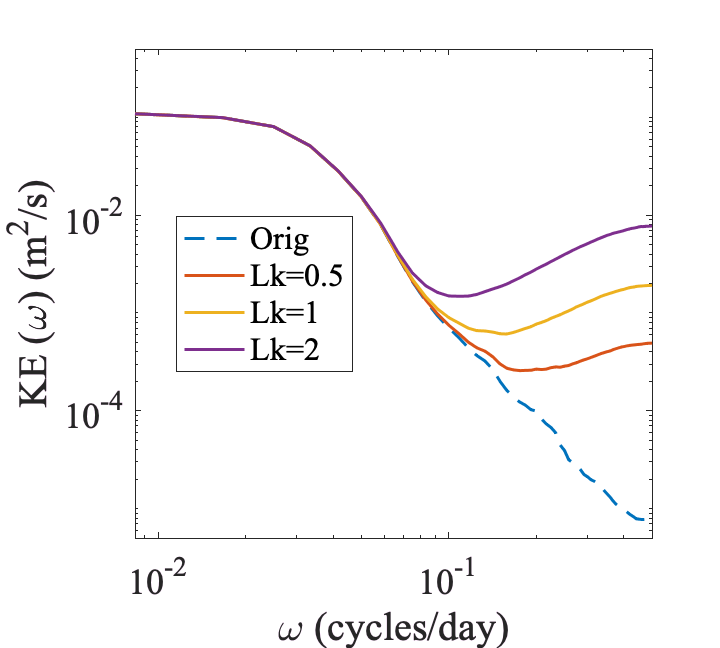

% Plot frequency spec with noise 

figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters') 
colors = get(gca,'Colororder');
%h(1) = shadedErrorBar_log(F_obs, SPP_obs_mean, SPP_obs_ci, ...
%        {'--','linewidth',2,'color', colors(2,:)}, 1);
    %loglog(F_obs, mean(SPP_obs(:, id),2),'--', 'linewidth',2,'color', [0.3010    0.7450    0.9330])
%hold all
%loglog(F_obs, mean(SNN_obs(:, id),2), '-', 'linewidth',2,'color', [0.3010    0.7450    0.9330])
%h(2) = shadedErrorBar_log(F_obs, SNN_obs_mean, SNN_obs_ci, ...
%        {'-','linewidth',2,'color', colors(2,:)}, 1);
%loglog(F_mod, nanmean(SPP_mod,2), 'linewidth',1, 'color',[0.8500    0.3250    0.0980])
%loglog(F_mod, nanmean(SNN_mod,2), '--', 'linewidth',1, 'color',[0.8500    0.3250    0.0980])

%loglog(F_mod, nanmean(SPP_mod2,2), '--','linewidth',2, 'color',[0.8500    0.3250    0.0980])
m(1) =loglog(F_mod_noise, nanmean(SPP_mod + SNN_mod,2), '--','linewidth',1.5, 'color',colors(1,:));
hold all 
m(2) =loglog(F_mod_noise, nanmean(SPP_mod_noise1 + SNN_mod_noise1,2), '-', 'linewidth',1.5, 'color',colors(2,:));
m(3) =loglog(F_mod_noise, nanmean(SPP_mod_noise2 + SNN_mod_noise2,2), '-', 'linewidth',1.5, 'color',colors(3,:));
m(4) =loglog(F_mod_noise, nanmean(SPP_mod_noise3 + SNN_mod_noise3,2), '-', 'linewidth',1.5, 'color',colors(4,:));

legend('Orig', 'Lk=0.5', 'Lk=1', 'Lk=2', 'location', 'best')

set(gca, 'fontsize', 18, 'fontname', 'times') 
xlabel('\omega (cycles/day)')
ylabel('KE (\omega) (m^2/s)')

xlim([1/120, 1/2])
ylim([5e-6, 0.5])
print('noise_freq.eps', '-depsc', '-r400')

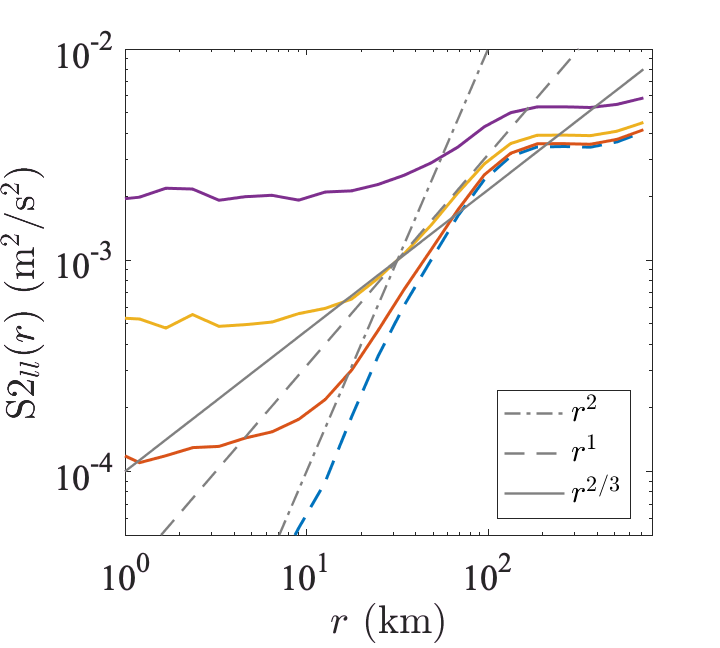

% deep figure
clear h g 
%figure('rend','painters','pos',[10 10 800 600])
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters')
        
g(1) = loglog(dist_axis/1e3, S2ll_mod, '--', 'linewidth',1.5,'color',colors(1,:));
hold all 
g(2) = loglog(dist_axis/1e3, S2ll_mod_noise1, '-', 'linewidth',1.5,'color', colors(2,:));
g(2) = loglog(dist_axis/1e3, S2ll_mod_noise2, '-', 'linewidth',1.5,'color', colors(3,:));
g(2) = loglog(dist_axis/1e3, S2ll_mod_noise3, '-', 'linewidth',1.5,'color', colors(4,:));
%loglog(dist_axis/1e3, S2ll_mod_noise, '-', 'linewidth',1,'color', colors(7,:));
%r0 = loglog(dist_axis/1e3, dist_axis./dist_axis*0.1, '-','color', [0.5 0.5 0.5], 'linewidth',1);  
%r23 = loglog(dist_axis/1e3, 100*dist_axis.^(-2/3), '--', 'color', [0.5 0.5 0.5], 'linewidth',1); 
%r2 = loglog(dist_axis/1e3, 1e8*dist_axis.^(-2), '-.', 'color', [0.5 0.5 0.5], 'linewidth',1); 
r23 = loglog(dist_axis/1e3, 1e-6*dist_axis.^(2/3), '-','color', [0.5 0.5 0.5], 'linewidth',1.2);
r1 =loglog(dist_axis/1e3, 10^(-7.5)*dist_axis.^(1), '--','color', [0.5 0.5 0.5], 'linewidth',1.2);
r2 =loglog(dist_axis/1e3, 1e-12*dist_axis.^(2), '-.','color', [0.5 0.5 0.5], 'linewidth',1.2);

A = legend([r2, r1, r23], ...
    {  '$r^{2}$', '$r^{1}$', '$r^{2/3}$'} ...
    , 'Interpreter','Latex', 'location','best');

set(gca, 'fontsize', 18, 'fontname', 'times') 

axis([1 800 5e-5 1e-2])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('S2$_{ll} (r)$ (m$^{2}$/s$^{2}$)', 'Interpreter','Latex')
print('noise_S2.eps', '-depsc', '-r400')

% check dispersion 
ndays=100; 
Mod_disp = rel_disp(sep_mod.sep, ndays);
Mod_noise1_disp = rel_disp(sep_mod_noise1.sep, ndays);
Mod_noise2_disp = rel_disp(sep_mod_noise2.sep, ndays);
Mod_noise3_disp = rel_disp(sep_mod_noise3.sep, ndays);

Moddisp = Mod_disp.avdisp/1e6; 
Modnoise1disp = Mod_noise1_disp.avdisp/1e6; 
Modnoise2disp = Mod_noise2_disp.avdisp/1e6; 
Modnoise3disp = Mod_noise3_disp.avdisp/1e6; 

T = 0:99;

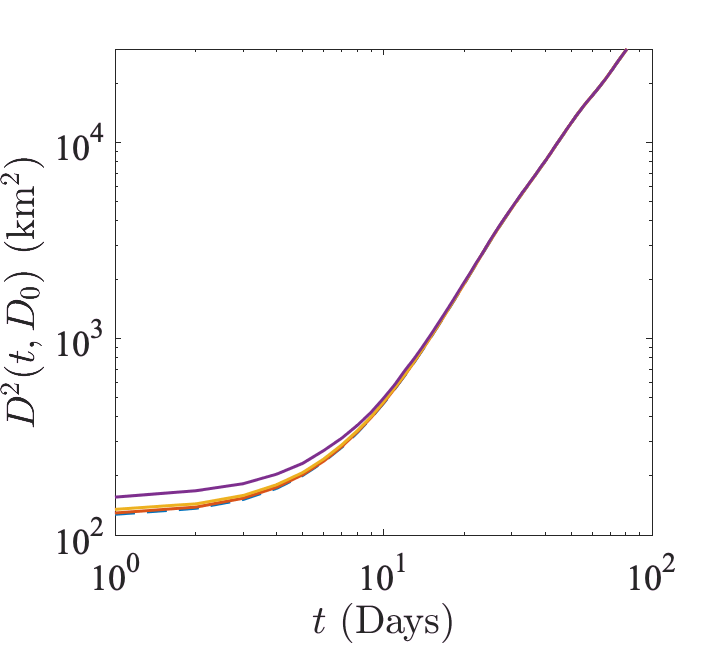

% Figure at first depth 
close all 
clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')
j=1;

g(i) = loglog(T+0.001, Moddisp, '--', 'color', colors(1,:), 'linewidth', 1.5);
hold all 
g(i) = loglog(T+0.001, Modnoise1disp, '-', 'color', colors(2,:), 'linewidth', 1.5);    
g(i) = loglog(T+0.001, Modnoise2disp, '-', 'color', colors(3,:), 'linewidth', 1.5);    
g(i) = loglog(T+0.001, Modnoise3disp, '-', 'color', colors(4,:), 'linewidth', 1.5);    

Tax= T(5:50);
%t3 = loglog(Tax, 10^0.7*Tax.^3,'--', 'color', [0.5 0.5 0.5], 'linewidth', 1.);
%t2 = loglog(Tax, 10^8.15*Tax.^2,'-.', 'color', [0.5 0.5 0.5]);
%t1 = loglog(Tax, 10^3.*Tax, 'color', [0.5 0.5 0.5], 'linewidth', 1.);


%A = legend([h(1).mainLine,h(2).mainLine,  g, t3, t1], ...
%    {'Obs 10-15km', 'Obs 30-35km', 'Mod 11km', 'Mod 33km','~t^3','~t'},'location','best','fontsize',14); 
axis([1 100 10^2 3*10^4])
%legend boxoff
%set(A, 'location','best')
set(gca,'FontSize', 18,'fontname','times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('$D^2(t, D_0)$ (km$^2$)', 'Interpreter','Latex')
print('noise_disp.eps', '-depsc', '-r400')

% check relative diffusivity

mod_sep_for_sep = model_sep_calcs(mod_traj, [0, 50]*1e3); 
mod_noise1_sep_for_sep = model_sep_calcs(mod_traj_noise(1), [0, 50]*1e3); 
mod_noise2_sep_for_sep = model_sep_calcs(mod_traj_noise(2), [0, 50]*1e3); 
mod_noise3_sep_for_sep = model_sep_calcs(mod_traj_noise(3), [0, 50]*1e3); 

rd1_mod= rel_diff_inst_model(mod_sep_for_sep.sep, dist_bin,1); 
rd1_mod_noise1= rel_diff_inst_model(mod_noise1_sep_for_sep.sep, dist_bin,1); 
rd1_mod_noise2= rel_diff_inst_model(mod_noise2_sep_for_sep.sep, dist_bin,1); 
rd1_mod_noise3= rel_diff_inst_model(mod_noise3_sep_for_sep.sep, dist_bin,1); 

rd6_mod= rel_diff_inst_model(mod_sep_for_sep.sep, dist_bin,6); 
rd6_mod_noise1= rel_diff_inst_model(mod_noise1_sep_for_sep.sep, dist_bin,6); 
rd6_mod_noise2= rel_diff_inst_model(mod_noise2_sep_for_sep.sep, dist_bin,6); 
rd6_mod_noise3= rel_diff_inst_model(mod_noise3_sep_for_sep.sep, dist_bin,6); 

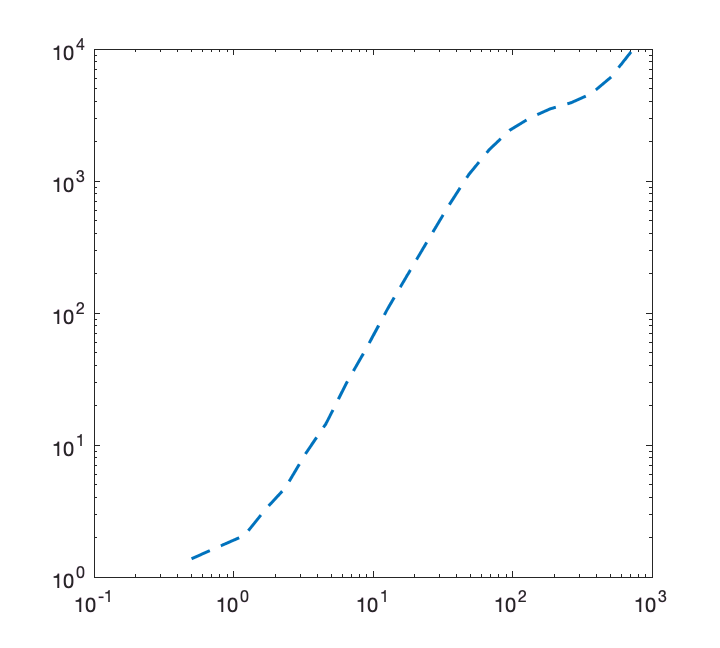

clear h g 
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')


g(1) = loglog(dist_axis/1e3, rd6_mod.rdmean,'--', 'linewidth',1.5,'color', colors(1,:));
hold all

g(2) = loglog(dist_axis/1e3, rd6_mod_noise1.rdmean,'-', 'linewidth',1.5,'color', colors(2,:));

Undefined variable "rd6_mod_noise1" or class "rd6_mod_noise1.rdmean".

g(3) = loglog(dist_axis/1e3, rd6_mod_noise2.rdmean,'-', 'linewidth',1.5,'color', colors(3,:));
g(4) = loglog(dist_axis/1e3, rd6_mod_noise3.rdmean,'-', 'linewidth',1.5,'color', colors(4,:));


r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 5e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


A = legend([r2, r43], ...
    {'$r^{2}$', '$r^{4/3}$'}, 'location', 'best' ...
    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 500 10 5e3])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('noise_diff6.eps', '-depsc', '-r400')

clear h g 
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')


g(1) = loglog(dist_axis/1e3, rd1_mod.rdmean,'--', 'linewidth',1.5,'color', colors(1,:));
hold all
g(2) = loglog(dist_axis/1e3, rd1_mod_noise1.rdmean,'-', 'linewidth',1.5,'color', colors(2,:));
g(3) = loglog(dist_axis/1e3, rd1_mod_noise2.rdmean,'-', 'linewidth',1.5,'color', colors(3,:));
g(4) = loglog(dist_axis/1e3, rd1_mod_noise3.rdmean,'-', 'linewidth',1.5,'color', colors(4,:));


r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 5e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


%A = legend([r2, r43], ...
%    {'$r^{2}$', '$r^{4/3}$'}, 'location', 'best' ...
%    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 500 10 5e3])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('noise_diff.eps', '-depsc', '-r400')

% Check FSLE
flag_1time= 1;
fsle_mod = fsle_model(mod_sep_for_sep.sep, dist_bin, 1, flag_1time); 
fsle_mod_noise1 = fsle_model(mod_noise1_sep_for_sep.sep, dist_bin, 1, flag_1time); 
fsle_mod_noise2 = fsle_model(mod_noise2_sep_for_sep.sep, dist_bin, 1, flag_1time); 
fsle_mod_noise3 = fsle_model(mod_noise3_sep_for_sep.sep, dist_bin, 1, flag_1time); 


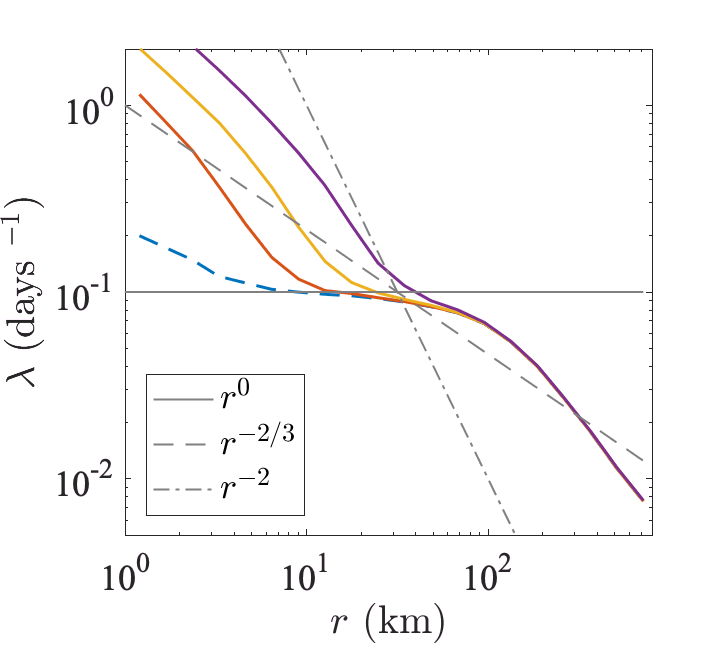

%% Figure for deep
close all 
clear h g 
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters')

        
%g(1) = loglog(dist_axis/1e3, fsle_mod_deep, '--', 'linewidth',2,'color', colors(2,:));
g(1) = loglog(dist_axis/1e3, fsle_mod, '--', 'linewidth',1.5, 'color', colors(1,:)); 
hold all 
g(2) = loglog(dist_axis/1e3, fsle_mod_noise1, '-', 'linewidth',1.5, 'color', colors(2,:)); 
g(3) = loglog(dist_axis/1e3, fsle_mod_noise2, '-', 'linewidth',1.5, 'color', colors(3,:)); 
g(4) = loglog(dist_axis/1e3, fsle_mod_noise3, '-', 'linewidth',1.5, 'color', colors(4,:)); 

r0 = loglog(dist_axis/1e3, dist_axis./dist_axis*0.1, '-','color', [0.5 0.5 0.5], 'linewidth',1);  
r23 = loglog(dist_axis/1e3, 100*dist_axis.^(-2/3), '--', 'color', [0.5 0.5 0.5], 'linewidth',1); 
r2 = loglog(dist_axis/1e3, 1e8*dist_axis.^(-2), '-.', 'color', [0.5 0.5 0.5], 'linewidth',1); 


A = legend([ r0, r23, r2], ...
    {'$r^{0}$', '$r^{-2/3}$', '$r^{-2}$'} ...
    , 'Interpreter','Latex', 'location','southwest', 'fontsize',18);
%legend boxoff
%set(A, 'location','best') 
set(gca, 'fontsize', 18, 'fontname','times') 

axis([1 800 50*1e-4 2])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$\lambda$ (days $^{-1}$)', 'Interpreter','Latex')
print('noise_FSLE.eps', '-depsc', '-r400')